clear; close all; clc;

% ---------------------- SERIAL CONFIG ----------------------
delete(instrfind);

PSoC = serial('COM10', 'BaudRate', 115200, 'InputBufferSize', 30000);

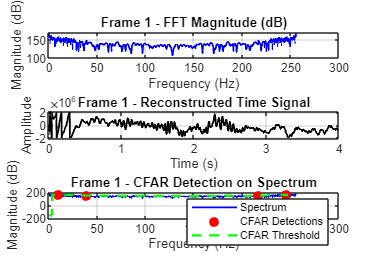

Frame 1 processed and displayed.


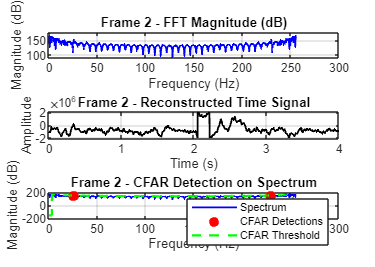

Frame 2 processed and displayed.


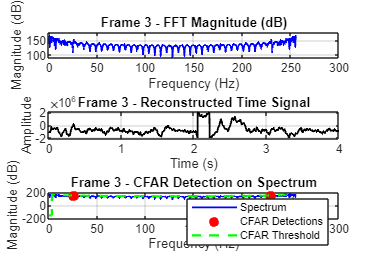

Frame 3 processed and displayed.


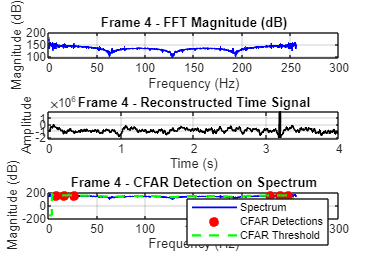

Frame 4 processed and displayed.


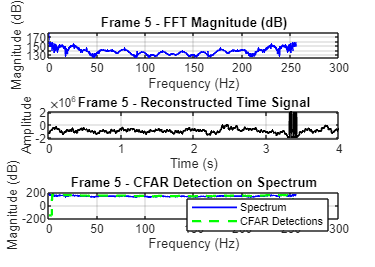

Frame 5 processed and displayed.


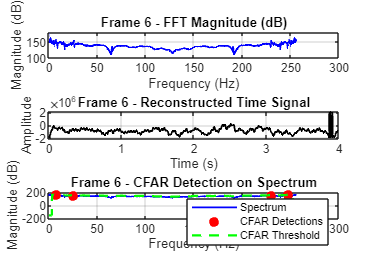

Frame 6 processed and displayed.


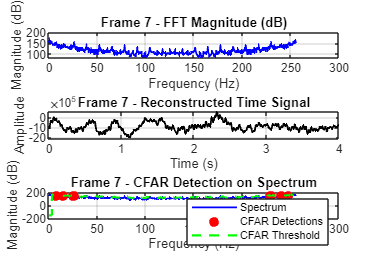

Frame 7 processed and displayed.


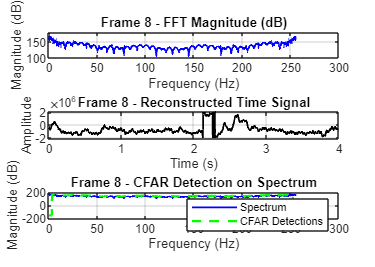

Frame 8 processed and displayed.


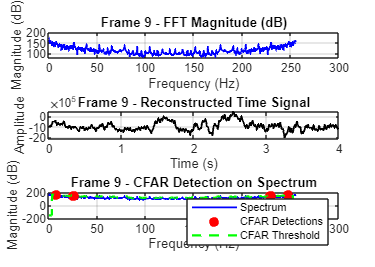

Frame 9 processed and displayed.


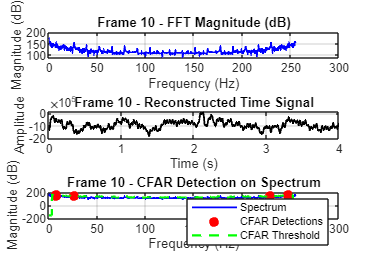

Frame 10 processed and displayed.


fopen(PSoC);

% ---------------------- PARAMETERS -------------------------
numSamples = 1024;
numFrames  = 10;
timeout    = 5;

% Sampling parameters (replace Fs with actual value if known)
Fs = 256;                                 % Sampling frequency in Hz (update as needed)
t = (0:numSamples-1) / Fs;              % Time axis for time-domain signal
f = (0:numSamples-1); % Frequency axis for FFT plots

% CFAR parameters (must match your embedded implementation)
NG = 2;        % Guard cells
NR = 12;       % Reference cells
PFA = 1e-2;    % Updated to match embedded code
alpha = NR * (PFA^(-1/NR) - 1);

% ---------------------- MAIN LOOP --------------------------
for count = 1:numFrames
    fwrite(PSoC, 's', 'uchar');  % Request data

    % Total bytes expected:
    % FFT data: 2 * numSamples * 4 bytes (int32)
    % CFAR flags: numSamples * 1 byte (uint8)
    bytesFFT = 4 * 2 * numSamples;
    bytesCFAR = numSamples;
    totalBytes = bytesFFT + bytesCFAR;

    tStart = tic;
    while PSoC.BytesAvailable < totalBytes
        pause(0.01);
        if toc(tStart) > timeout
            warning('Timeout on frame %d', count);
            break;
        end
    end

    fwrite(PSoC, 'o', 'uchar');  % Acknowledge

    % Read FFT data
    fft_raw = fread(PSoC, 2 * numSamples, 'int32');
    if numel(fft_raw) < 2 * numSamples
        warning('Incomplete FFT data on frame %d', count);
        break;
    end

    % Read CFAR detection flags
    cfar_detected = fread(PSoC, numSamples, 'uint8');
    if numel(cfar_detected) < numSamples
        warning('Incomplete CFAR detection data on frame %d', count);
        break;
    end

    % Complex FFT and signal reconstruction
    fft_complex = fft_raw(1:2:end) + 1i * fft_raw(2:2:end);
    signal_rec = real(ifft(fft_complex));

    % Power spectrum and dB
    X_power = abs(fft_complex).^2;
    X_dB = 10 * log10(X_power + eps);

    % --- Calculate noise threshold for each bin (like embedded CFAR) ---
    noise_threshold = zeros(numSamples,1);
    for i = NR + NG + 1 : numSamples - (NR + NG)
        noise_sum = 0;
        % Leading reference cells
        for j = i - NR - NG : i - NG - 1
            noise_sum = noise_sum + X_power(j);
        end
        % Lagging reference cells
        for j = i + NG + 1 : i + NG + NR
            noise_sum = noise_sum + X_power(j);
        end
        noise_avg = noise_sum / (2 * NR);
        noise_threshold(i) = alpha * noise_avg;
    end
    noise_threshold_dB = 10 * log10(noise_threshold + eps);

    % --- Suppress detections on DC and near edges ---
    cfar_detected(1:NR+NG) = 0;
    cfar_detected(end-(NR+NG-1):end) = 0;
    cfar_detected(1) = 0;

    % ---------------------- PLOTTING -------------------------
    figure('Name', sprintf('Frame %d', count), 'Position', [100, 100, 1200, 900]);

    subplot(3,1,1);
    plot(f, X_dB, 'b', 'LineWidth', 1.2);
    title(sprintf('Frame %d - FFT Magnitude (dB)', count));
    xlabel('Frequency (Hz)');
    ylabel('Magnitude (dB)');
    grid on;

    subplot(3,1,2);
    plot(t, signal_rec, 'k', 'LineWidth', 1.2);
    title(sprintf('Frame %d - Reconstructed Time Signal', count));
    xlabel('Time (s)');
    ylabel('Amplitude');
    grid on;

    subplot(3,1,3);
    plot(f, X_dB, 'b', 'LineWidth', 1.2); hold on;
    plot(f(cfar_detected == 1), X_dB(cfar_detected == 1), 'ro', 'MarkerFaceColor', 'r');
    plot(f, noise_threshold_dB, 'g--', 'LineWidth', 1.5);  % CFAR threshold line
    title(sprintf('Frame %d - CFAR Detection on Spectrum', count));
    xlabel('Frequency (Hz)');
    ylabel('Magnitude (dB)');
    legend('Spectrum', 'CFAR Detections', 'CFAR Threshold');
    grid on;

    drawnow;
    fprintf("Frame %d processed and displayed.\n", count);
end


% ---------------------- CLOSE SERIAL ------------------------
fclose(PSoC);
delete(PSoC);
clear PSoC;

fprintf("All frames complete.\n");

All frames complete.
